# Langtidsdrift

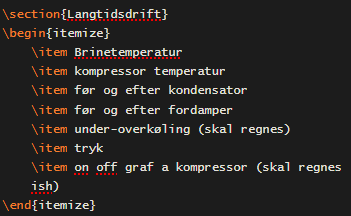

clc; clear all;


LTD = importdata("LangTidsDrift.txt");



## Brine


LTD_Tbrine = find(LTD.textdata(1,2:end) == "Brinetemperatur")

LTD_Tbrine = 4




ind = 10;

LTD_Tbrine = LTD.data(ind:end-ind, LTD_Tbrine);



ind_plot = find(max(LTD_Tbrine) == LTD_Tbrine)

ind_plot = 12958


xs = length(LTD_Tbrine(ind:end))*2*0.142/60

xs = 69.9113

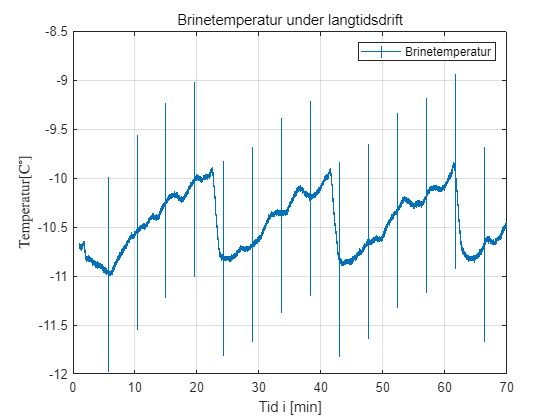


xlin = linspace(1,xs, length(LTD_Tbrine(ind:end)));


lps = length(xlin);

errlin = zeros(1,lps);

fejl = 0.9798;

for i = 1:lps
    if mod(i,1000) == 0
        errlin(i) = 1;
    else
        errlin(i) = 0;
    end
    
end



figure

errorbar(xlin, LTD_Tbrine(ind:end),errlin,"CapSize",0)
hold on


grid("on")
title("Brinetemperatur under langtidsdrift","FontWeight","normal")
xlabel("Tid i [min]")
ylabel("Temperatur[C$^\circ$]","Interpreter","latex")
legend("Brinetemperatur")

exportgraphics(gcf,"BrineTempLangtidsdrift.png")

## Tryk

LTD_lavtryk = find(LTD.textdata(1,2:end) == "Tryk lav")

LTD_lavtryk = 13

LTD_hojtryk = find(LTD.textdata(1,2:end) == "Tryk høj")

LTD_hojtryk = 12


LTD_lavtryk = LTD.data(ind:end-10, LTD_lavtryk) +1;
LTD_hojtryk = LTD.data(ind:end-10, LTD_hojtryk) +1;

errlin_hoj = zeros(1,lps);
errlin_lav = zeros(1,lps);

fejlhoj = 0.008*20;
fejllav = 0.008*12;

for i = 1:lps
    if mod(i,1000) == 0
        errlin_hoj(i) = fejlhoj;
        errlin_lav(i) = fejllav;
    else
        errlin_hoj(i) = 0;
        errlin_lav(i) = 0;
    end
    
end


inthoj = [LTD_hojtryk(ind:end)-fejlhoj,LTD_hojtryk(ind:end)+fejlhoj]

inthoj =     6.3802    6.7002
    6.3631    6.6831
    6.3665    6.6865
    6.3751    6.6951
    6.3717    6.6917
    6.3751    6.6951
    6.3751    6.6951
    6.3768    6.6968
    6.3802    6.7002
    6.3802    6.7002


intlav = [LTD_lavtryk(ind:end)-fejllav,LTD_lavtryk(ind:end)+fejllav]

intlav =     0.1557    0.3477
    0.1705    0.3625
    0.2234    0.4154
    0.2975    0.4895
    0.3757    0.5677
    0.4572    0.6492
    0.5344    0.7264
    0.6084    0.8004
    0.6824    0.8744
    0.7522    0.9442


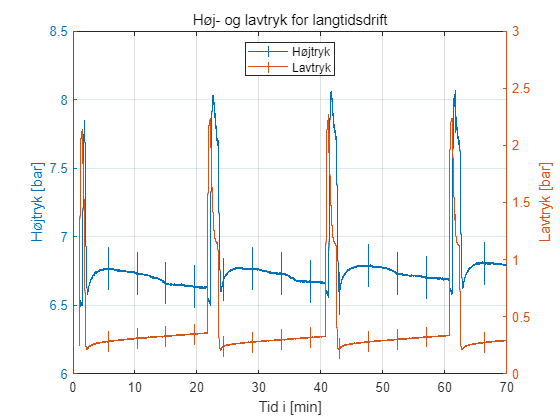



figure

yyaxis left
errorbar(xlin, LTD_hojtryk(1:end-9),errlin_hoj,"CapSize",0)


ylabel("Højtryk [bar]")
ylim([6,8.5])

yyaxis right
errorbar(xlin, LTD_lavtryk(1:end-9),errlin_lav,"CapSize",0)

ylabel("Lavtryk [bar]")

ylim([0,3])

grid("on")
legend("Højtryk","Lavtryk","Location","north")
title("Høj- og lavtryk for langtidsdrift","FontWeight","normal")
xlabel("Tid i [min]")

exportgraphics(gcf,"HojLavTrykLangtidsdrift.png")

## Entalpier

## Temp før og efter kondensator



T_kond_for   = find(LTD.textdata(1,2:end) == "Temperatur efter kompressor")

T_kond_for = 10

T_kond_efter = find(LTD.textdata(1,2:end) == "Temperatur efter kondensator ")

T_kond_efter = 11

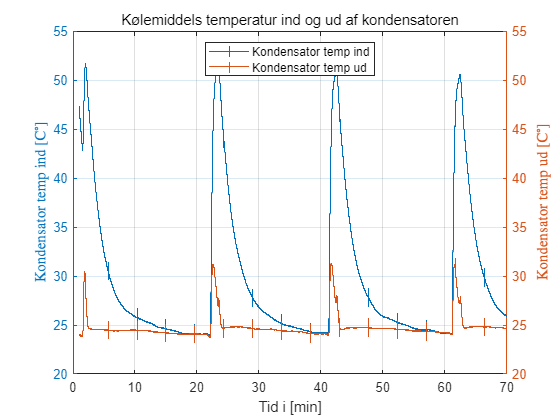




T_kond_for   = LTD.data(ind:end-19, T_kond_for);
T_kond_efter = LTD.data(ind:end-19, T_kond_efter);


figure

yyaxis left
errorbar(xlin, T_kond_for,errlin,"CapSize",0)
ylabel("Kondensator temp ind [C$^\circ$]", "Interpreter","latex")

ylim([20,55])

yyaxis right
errorbar(xlin, T_kond_efter,errlin,"CapSize",0)
ylabel("Kondensator temp ud [C$^\circ$]", "Interpreter","latex")
ylim([20,55])


grid("on")
legend("Kondensator temp ind","Kondensator temp ud","Location","north")
title("Kølemiddels temperatur ind og ud af kondensatoren","FontWeight","normal")
xlabel("Tid i [min]")


exportgraphics(gcf,"KondTempsLangtidsdrift.png")

## Temp før og efter fordamper


T_fordamp_for = find(LTD.textdata(1,2:end) == "Temperatur efter EPV")

T_fordamp_for = 9

T_fordamp_efter = find(LTD.textdata(1,2:end) == "Temperaturen efter fordamper")

T_fordamp_efter = 6

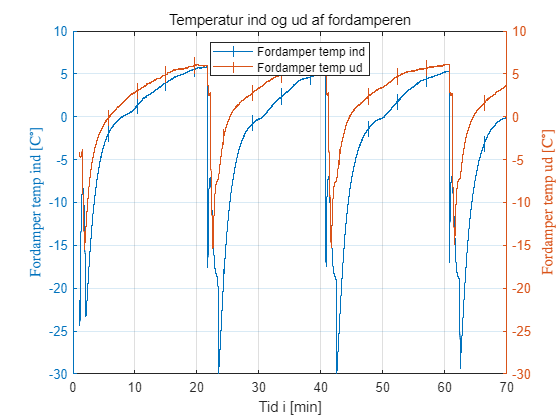



T_fordamp_for = LTD.data(ind:end-19, T_fordamp_for);
T_fordamp_efter = LTD.data(ind:end-19, T_fordamp_efter);


figure

yyaxis left
errorbar(xlin, T_fordamp_for,errlin,"CapSize",0)
ylabel("Fordamper temp ind [C$^\circ$]", "Interpreter","latex")

ylim([-30,10])

yyaxis right
errorbar(xlin, T_fordamp_efter,errlin,"CapSize",0)
ylabel("Fordamper temp ud [C$^\circ$]", "Interpreter","latex")

ylim([-30,10])

grid("on")
legend("Fordamper temp ind","Fordamper temp ud","Location","north")
title("Temperatur ind og ud af fordamperen","FontWeight","normal")
xlabel("Tid i [min]")

exportgraphics(gcf,"FordampTempsLangtidsdrift.png")

## Motortemperatur

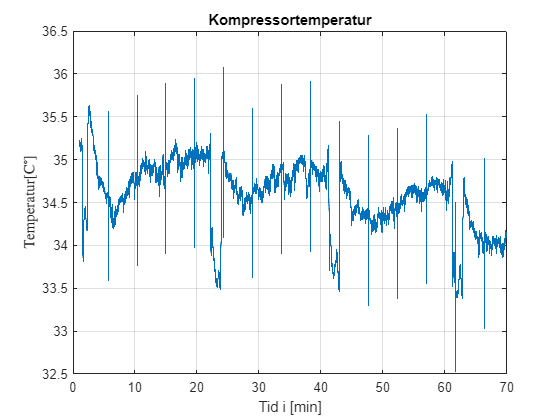

LTD_komptemp = find(LTD.textdata(1,2:end) == "Kompressortemperatur");

LTD_komptemp = LTD.data(ind:end-19, LTD_komptemp);


onoff = zeros(1, length(LTD_komptemp));

for i = 1:length(LTD_komptemp)
    if LTD_Tbrine(i) > -10.072
        onoff(i) = 1;
    else
        onoff(i) = -1;
    end
end

figure
errorbar(xlin,LTD_komptemp,errlin,"CapSize",0)

grid("on")
title("Kompressortemperatur")
ylabel("Temperatur[C$^\circ$]", "Interpreter","latex")
xlabel("Tid i [min]")

exportgraphics(gcf,"KompressorTemperaturLangtidsdrift.png")

## Kompressortemperatur

LTD_komptemp = find(LTD.textdata(1,2:end) == "Kompressortemperatur");

LTD_komptemp = LTD.data(ind:end-19, LTD_komptemp);


onoff = zeros(1, length(LTD_komptemp));

for i = 1:length(LTD_komptemp)
    if LTD_Tbrine(i) > -10.072
        onoff(i) = 1;
    else
        onoff(i) = -1;
    end
end


pts = [21.7448,-17.5891;23.4852,-30.9015;40.8192, -17.4496;42.5549,-30.4304;60.7241,-17.0383;62.4458,-29.3956]

pts =    21.7448  -17.5891
   23.4852  -30.9015
   40.8192  -17.4496
   42.5549  -30.4304
   60.7241  -17.0383
   62.4458  -29.3956


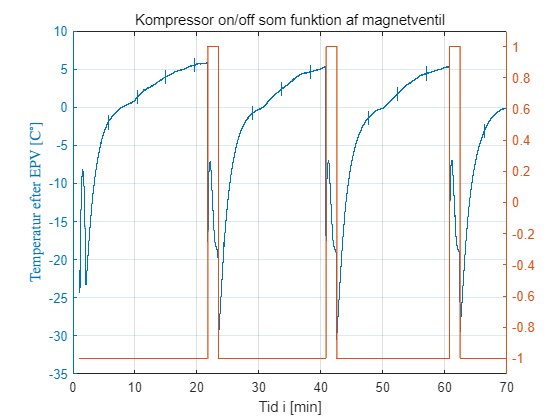



lin1 = ones(1,length(find(xlin < pts(1,1))))*-1;
lin2 = ones(1,abs(length(find(xlin < pts(2,1)))- length(find(xlin < pts(1,1)))));
lin3 = ones(1,abs(length(find(xlin < pts(3,1)))- length(find(xlin < pts(2,1)))))*-1;
lin4 = ones(1,abs(length(find(xlin < pts(4,1)))- length(find(xlin < pts(3,1)))));
lin5 = ones(1,abs(length(find(xlin < pts(5,1))) - length(find(xlin < pts(4,1)))))*-1;
lin6 = ones(1,abs(length(find(xlin < pts(6,1))) - length(find(xlin < pts(5,1)))));
lin7 = ones(1,length(find(xlin > pts(6,1))))*-1;


lin = [lin1,lin2,lin3,lin4,lin5,lin6,lin7];



figure
yyaxis left
errorbar(xlin, T_fordamp_for,errlin,"CapSize",0)

ylabel("Temperatur efter EPV [C$^\circ$]", "Interpreter","latex")



yyaxis right
plot(xlin, lin)

ylim([-1.1,1.1])

grid("on")
xlabel("Tid i [min]")
title("Kompressor on/off som funktion af magnetventil","FontWeight","normal")


exportgraphics(gcf,"KompressorONOFFLangtidsdrift.png")